Nome: Guilherme Tsubahara Horstmann e Marcos Davi de Oliveira

## **ANÁLISE DA RESPOSTA TRANSITÓRIA DE SISTEMAS DE 2ª ORDEM**

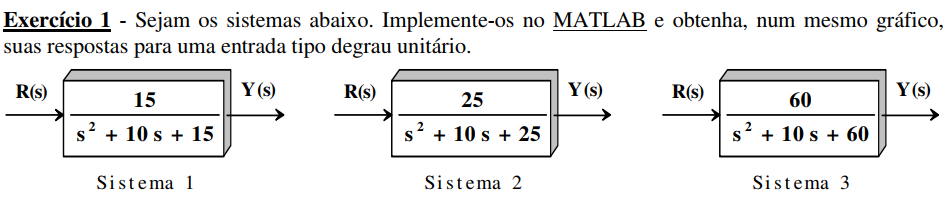

A partir dos sistemas apresentados no enunciado, plotamos os mesmos no gráfico abaixo.

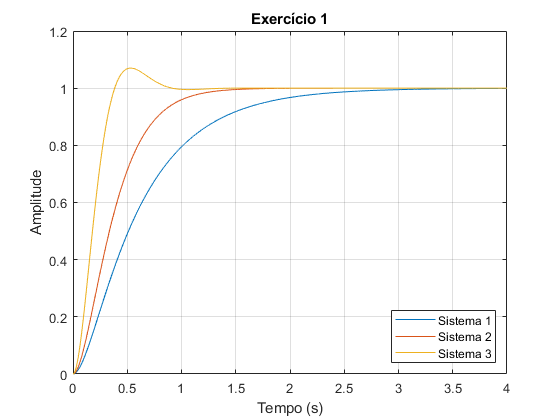

clc
clear all
close all

t = 0:0.001:4;
num1 = 15;
den1 = [1 10 15];
num2 = 25;
den2 = [1 10 25];
num3 = 60;
den3 = [1 10 60];
y1 = step(num1,den1,t);
y2 = step(num2,den2,t);
y3 = step(num3,den3,t);

plot(t,y1,t,y2,t,y3)
grid on
legend('Sistema 1', 'Sistema 2', 'Sistema 3', 'location', 'southeast')
xlabel('Tempo (s)')
ylabel('Amplitude')
title('Exercício 1')

p1 = roots(den1); %polos do sistema 1
p2 = roots(den2); %polos do sistema 2
p3 = roots(den3); %polos do sistema 3

Ao analisarmos os polos do sistema 1, sendo eles $-8\ldotp 1623$ e $-1\ldotp 8377$, é possível inferir que o sistema é superamortecido. Já observando os do sistema 2, sendo eles $-5$ e $-5$, dizemos o mesmo é criticamente amortecido, visto que as duas raizes são reais e iguais. Por fim, no sistema 3, cujo polos são $-5\pm 5,9161j$, temos que o sistema é subamortecido, visto que os polos são complexos conjulgados. 

Temos que o sistema na forma canônica de segunda ordem é dada pela seguinte expressão:


$$G\left(s\right)=\frac{\omega_n^2 }{s^2 +2\zeta \omega_n s+\omega_n^2 }$$


**Para o sistema 1, temos:**


$$G_1 \left(s\right)=\frac{15}{s^2 +10s+15}$$
      
$$\omega_n =\sqrt{15}=3,873$$
       
$$2\zeta \omega_n =10\to \zeta =\frac{\sqrt{15}}{3}=1,291$$


Logo, temos $\zeta >1$, caracterizando assim um sistema superamortecido, indo de acordo com o obtido no item anterior.

**Para o sistema 2, temos:**


$$G_2 \left(s\right)=\frac{25}{s^2 +10s+25}$$
      
$$\omega_n =\sqrt{25}=5$$
       
$$2\zeta \omega_n =10\to \zeta =1$$


Logo, temos $\zeta =1$, caracterizando assim um sistema criticamente amortecido, indo de acordo com o obtido no item anterior.

**Para o sistema 3, temos:**


$$G_3 \left(s\right)=\frac{60}{s^2 +10s+60}$$
      
$$\omega_n =\sqrt{60}=2\sqrt{15\;}=7,746$$
       
$$2\zeta \omega_n =10\to \zeta =\frac{\sqrt{15}}{6}=0,645$$


Logo, temos $0<\zeta <1$, caracterizando assim um sistema subamortecido, indo de acordo com o obtido no item anterior.

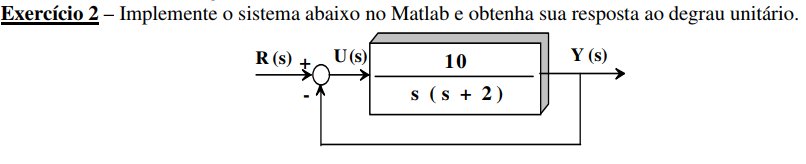

A partir do sistema apresentado no enunciado, plotamos o mesmo no gráfico abaixo.

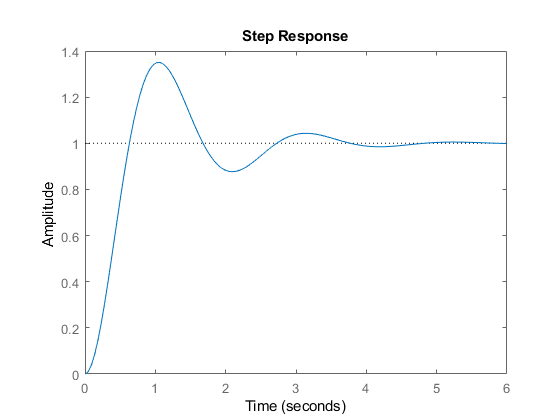

N1 = 10; D1 = [1 2 0]; % Definição de G(s)
N2 = 1; D2 = 1; % Definição de H(s)
[Nmf,Dmf] = feedback(N1,D1,N2,D2); % Obtenção da FT de malha fechada
step(Nmf,Dmf) % Aplicação do comando step à FTMF

$T=3,13-1,059=2,071s$       $\omega =\frac{2\pi }{T}=3,034$ rad/s

Logo, a resposta oscila com a frequência de $3,034$ rad/s.

 **No teórico**, temos que $G\left(s\right)=\frac{\frac{10}{s\left(s+2\right)}}{1+\frac{10}{s\left(s+2\right)}}=\frac{10}{s\left(s+2\right)+10}=\frac{10}{s^2 +2s+10}$

A partir disso, temos:

$\omega_n^2 =10\to \omega_n =3,162\;$rad/s


$$2\omega_n \zeta =2\to \zeta =\frac{1}{\omega_n }\to \zeta =316,2\times {10}^{-3}$$


$\omega_d =\omega_n \sqrt{1-\zeta^2 }\to \omega_d =3,000$ rad/s

**No prático**, a partir do gráfico, temos:

$\omega =3,034$ rad/s

Quando comparamos os dois, percebemos que a frequencia obtida pelo gráfico se aproxima mais da frequencia de oscilação amortecida $\omega_d$ do que da frequencia natural $\omega_n$.

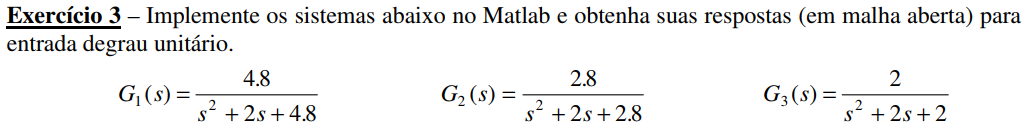

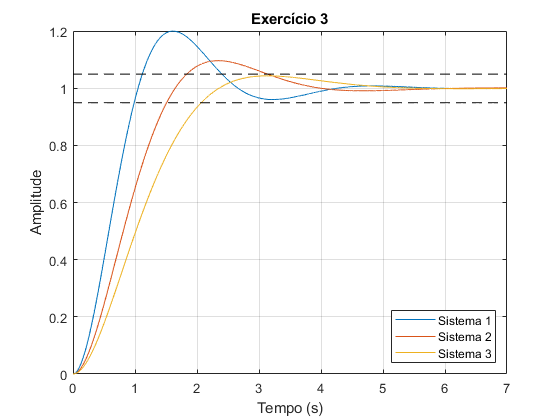

clc
clear all;
close all;

num1 = 4.8;
dem1 = [1 2 4.8];

num2 = 2.8;
dem2 = [1 2 2.8];

num3 = 2;
dem3 = [1 2 2];

t = 0:0.001:7;

y1 = step(num1,dem1,t);
y2 = step(num2,dem2,t);
y3 = step(num3,dem3,t);

ys1 = y1(end)*0.95;
ys2 = y1(end)*1.05;

ys1 = ys1*ones(length(t),1);
ys2 = ys2*ones(length(t),1);

plot(t,y1,t,y2,t,y3,t,ys1,'--k',t,ys2,'--k')
grid on
legend('Sistema 1', 'Sistema 2', 'Sistema 3', 'location', 'southeast')
xlabel('Tempo (s)')
ylabel('Amplitude')
title('Exercício 3')

p1 = roots(dem1); %polos do sistema 1
p2 = roots(dem2); %polos do sistema 2
p3 = roots(dem3); %polos do sistema 3

Para o sistema 1, temos os seguintes polos: $-1\pm 1,9494j$

Para o sistema 2, temos os seguintes polos: $-1\pm 1,3416j$

Continuamente, para o sistema 3, temos os seguintes polos: $-1\pm 1j$

Por fim, plotamos o mapa de polos e zeros dos três sistemas

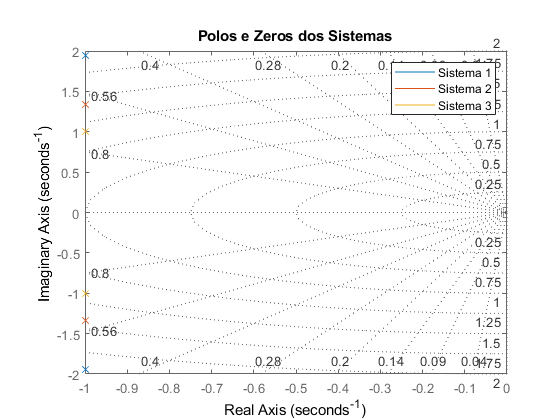

pzmap(num1, dem1)
hold on;
pzmap(num2,dem2)
pzmap(num3,dem3)
hold off;
grid on;
title('Polos e Zeros dos Sistemas')
legend('Sistema 1', 'Sistema 2', 'Sistema 3')

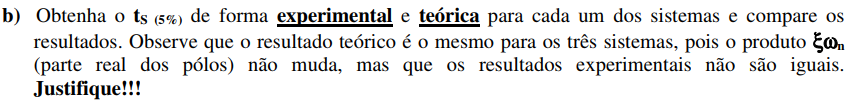

**Na forma experimental**, temos:

Para a sistema 1:


$$T_s \left(5%\right)=2,40s$$


Para o sistema 2:


$$T_s \left(5%\right)=3,17s$$


Para o sistema 3:


$$T_s \left(5%\right)=2,06s$$


**Na forma teórica**, temos:

Para a sistema 1:


$$\omega_n^2 =4,8\to \omega_n =2,19$$
                                                
$$2\zeta \omega_n =2\to \zeta =456,62\times {10}^{-3}$$



$$T_s \left(5%\right)=\frac{-\mathrm{ln}\left(0,05\sqrt{1-\zeta^2 }\right)}{\zeta \omega_n }\to T_s \left(5%\right)=3,11s$$


Para o sistema 2:


$$\omega_n^2 =2,8\to \omega_n =1,67$$
                                                
$$2\zeta \omega_n =2\to \zeta =598,80\times {10}^{-3}$$



$$T_s \left(5%\right)=\frac{-\mathrm{ln}\left(0,05\sqrt{1-\zeta^2 }\right)}{\zeta \omega_n }\to T_s \left(5%\right)=3,22s$$


Para o sistema 3:


$$\omega_n^2 =2\to \omega_n =1,41$$
                                                
$$2\zeta \omega_n =2\to \zeta =709,22\times {10}^{-3}$$



$$T_s \left(5%\right)=\frac{-\mathrm{ln}\left(0,05\sqrt{1-\zeta^2 }\right)}{\zeta \omega_n }\to T_s \left(5%\right)=3,35s$$


Ao comparamos os valores teóricos com os simulados, percebe-se que há divergências entre os valores. Isso se deve pois as formulas utilizadas para calcular $T_s \left(5%\right)$ são aproximadas.

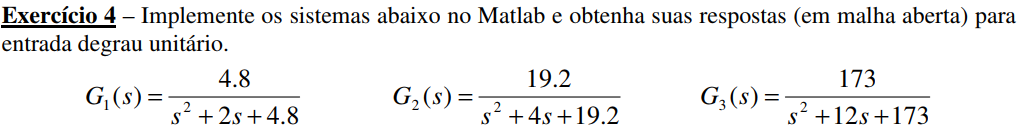

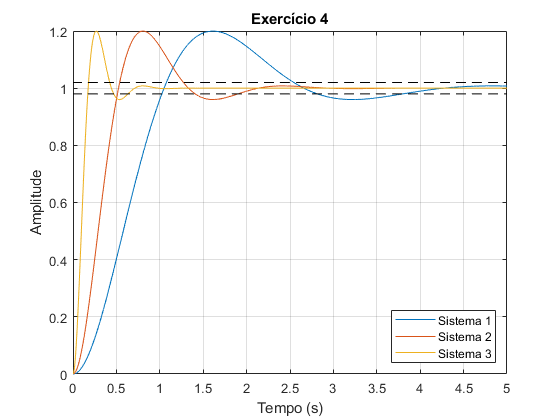

clc
clear all;
close all;

num1 = 4.8;
dem1 = [1 2 4.8];

num2 = 19.2;
dem2 = [1 4 19.2];

num3 = 173;
dem3 = [1 12 173];

t = 0:0.001:5;

y1 = step(num1,dem1,t);
y2 = step(num2,dem2,t);
y3 = step(num3,dem3,t);

ys1 = 1*0.98;
ys2 = 1*1.02;

ys1 = ys1*ones(length(t),1);
ys2 = ys2*ones(length(t),1);

plot(t,y1,t,y2,t,y3,t,ys1,'--k',t,ys2,'--k')
grid on
legend('Sistema 1', 'Sistema 2', 'Sistema 3', 'location', 'southeast')
xlabel('Tempo (s)')
ylabel('Amplitude')
title('Exercício 4')

p1 = roots(dem1); %polos do sistema 1
p2 = roots(dem2); %polos do sistema 2
p3 = roots(dem3); %polos do sistema 3

Para o sistema 1, temos os seguintes polos: $-1\pm 1,9494j$

Para o sistema 2, temos os seguintes polos: $-2\pm 3,8987j$

Continuamente, para o sistema 3, temos os seguintes polos: $-6\pm 11,7074j$

Por fim, plotamos o mapa de polos e zeros dos três sistemas

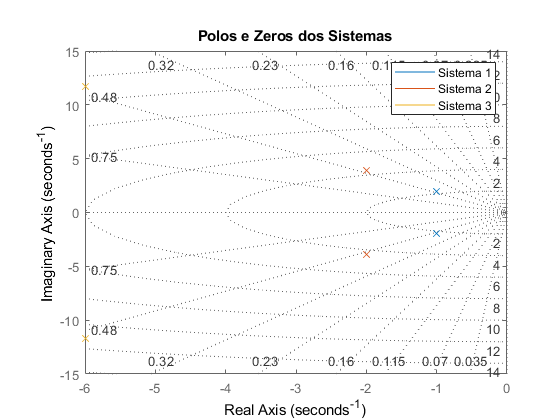

pzmap(num1, dem1)
hold on;
pzmap(num2,dem2)
pzmap(num3,dem3)
hold off;
grid on;
title('Polos e Zeros dos Sistemas')
legend('Sistema 1', 'Sistema 2', 'Sistema 3')

Se analisarmos o gráfico, é possíve ver que o sobresinal de todos os sistemas são iguais, logo, podemos calcular apenas uma vez.


$$%\mathrm{OS}=\frac{1,2-1}{1}\times 100=20%$$


Isso se deve pois, se analisamos o gráfico de polos e zeros apresentados na item anterior, é possível ver os polos tem o mesmo ângulo, cusando desse modo o mesmo valor de sobresinal.

Para isso, analisamos o gráfico do item a e motamos a tabela abaixo.


$$\left\lbrack \begin{array}{cccc}
 & T_p  & T_s \left(2%\right) & %\mathrm{OS}\\
G_1 \left(s\right) & 1\ldotp 609 & 3\ldotp 821 & 20%\\
G_2 \left(s\right) & 0\ldotp 792 & 1\ldotp 893 & 20%\\
G_3 \left(s\right) & 0\ldotp 267 & 0\ldotp 636 & 20%
\end{array}\right\rbrack$$


Novamente, se observamos, percebemos que o sobresinal é constante em todos os sistemas, entretando os valores de $T_p$ e $T_s \left(2%\right)$ divergem, isso se deve pois os valores reais e imaginários dos polos variam de sistema para sistema.

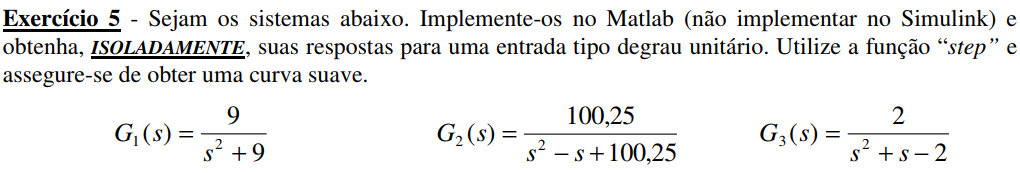

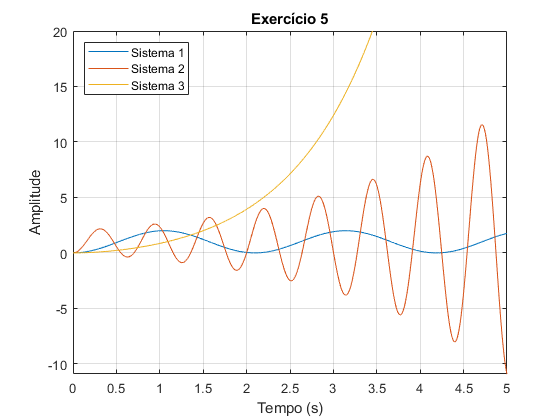

clc
clear all;
close all;

num1 = 9;
dem1 = [1 0 9];

num2 = 100.25;
dem2 = [1 -1 100.25];

num3 = 2;
dem3 = [1 1 -2];

t = 0:0.001:5;

y1 = step(num1,dem1,t);
y2 = step(num2,dem2,t);
y3 = step(num3,dem3,t);

plot(t,y1,t,y2,t,y3)
grid on
legend('Sistema 1', 'Sistema 2', 'Sistema 3', 'location', 'northwest')
axis([-inf +inf -inf 20])
xlabel('Tempo (s)')
ylabel('Amplitude')
title('Exercício 5')

p1 = roots(dem1); %polos do sistema 1
p2 = roots(dem2); %polos do sistema 2
p3 = roots(dem3); %polos do sistema 3

Para o sistema 1, temos os seguintes polos: $\pm 3j$

Para o sistema 2, temos os seguintes polos: $-0\ldotp 5\pm 10j$

Continuamente, para o sistema 3, temos os seguintes polos: $-2$ e $1$

Por fim, plotamos o mapa de polos e zeros dos três sistemas

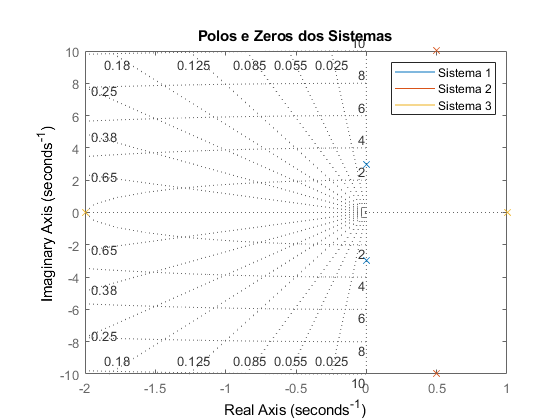

pzmap(num1, dem1)
hold on;
pzmap(num2,dem2)
pzmap(num3,dem3)
hold off;
grid on;
title('Polos e Zeros dos Sistemas')
legend('Sistema 1', 'Sistema 2', 'Sistema 3')

Quando analisamos o gráfico do item anterior, temos:


$$\left\lbrack \begin{array}{cc}
 & \mathrm{Classificação}\\
G_1 \left(s\right) & \mathrm{Marginalmente}\;\mathrm{Instável}\\
G_2 \left(s\right) & \mathrm{Instável}\\
G_3 \left(s\right) & \mathrm{Instável}
\end{array}\right\rbrack$$
